Caso de Estudio.- Sguridad en reactores Nucleares. Ecuación del transporte de Neutrones ( Ecuación de los modos Lambda)

Trabajaremos con el reactor Biblis. Es un caso 2D.

Primero cargamos los datos del reactor Biblis, para la discretización con polinomios de grado 2.

load biblis2.mat
whos

  Name          Size               Bytes  Class     Attributes    

  A           438x438            1534752  double                  
  B           438x438            1534752  double                  
  D           438x438            1534752  double                  
  D1          438x438            1534752  double                  
  L           438x438              62536  double    sparse        
  L11         219x219              29456  double    global, sparse
  L21         219x1                 1752  double    global        
  L22         219x219              29584  double    global, sparse
  M           438x438               8888  double    sparse        
  M11         219x1                 1752  double    global        
  M12         219x1                 1752  double    global        
  V           438x438            1534752  double                  
  V1          438x438            1534752  double                  
  ans           1x1                    8  double             

disp('Analizar las dimensiones de las matrices y la memoria en Bytes')

Analizar las dimensiones de las matrices y la memoria en Bytes


Vamos a alamcenar la matriz L en formato denso

A=full(L);
whos A L

  Name        Size               Bytes  Class     Attributes

  A         438x438            1534752  double              
  L         438x438              62536  double    sparse    



B=full(M);

Se aprecia una diferencia notable en los requerimientos de memoria, ¿puesde indicar el % de reducción si se emplea el formato disperso?

Ahora vamos a visualizar la estructura de la matriz L y M que aproximan a los operadores de generación y perdida de neutrones respectivamente.

disp('Estrucutura de la matriz L')

Estrucutura de la matriz L


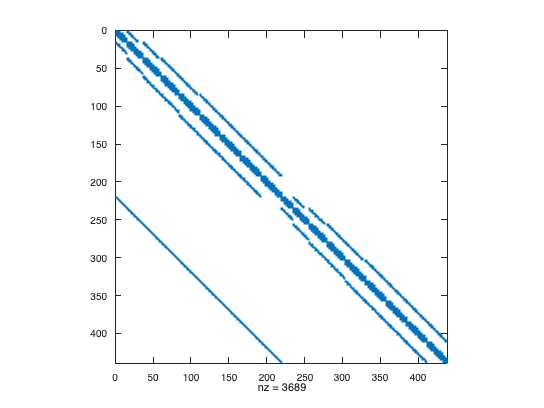

spy(L)

disp('Estrucutura de la matriz M')

Estrucutura de la matriz M


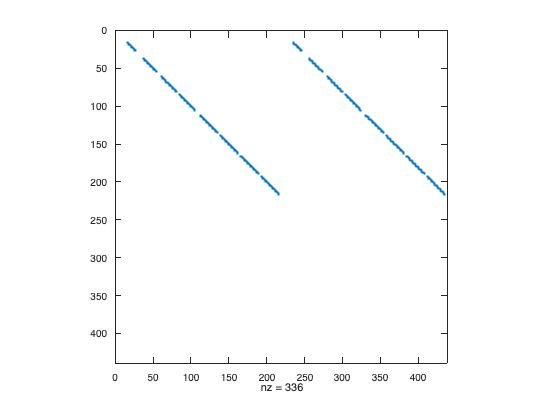

spy(M)

Ahora valos a resolver el problema de autovalores  L* x = lambda*M*x. Para ello vamos a resolver                              x=L^-1(lambda*M*x)= lambda( L^-1*M)x


tic
[V,D]= eigs(M,L,6);
disp('el tiempo de ejecución es:')

el tiempo de ejecución es:


toc

Elapsed time is 0.020316 seconds.


whos

  Name          Size               Bytes  Class     Attributes    

  A           438x438            1534752  double                  
  B           438x438            1534752  double                  
  D             6x6                  288  double                  
  D1          438x438            1534752  double                  
  L           438x438              62536  double    sparse        
  L11         219x219              29456  double    global, sparse
  L21         219x1                 1752  double    global        
  L22         219x219              29584  double    global, sparse
  M           438x438               8888  double    sparse        
  M11         219x1                 1752  double    global        
  M12         219x1                 1752  double    global        
  V           438x6                21024  double                  
  V1          438x438            1534752  double                  
  ans           1x1                    8  double             

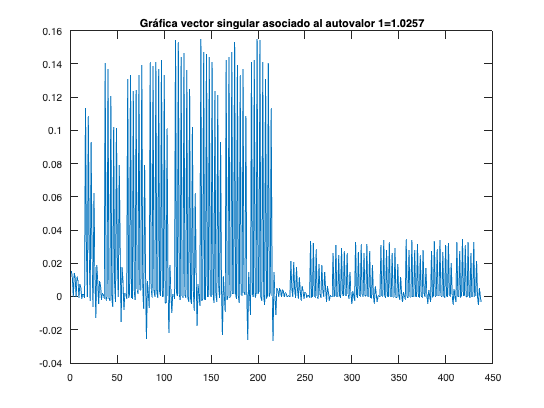

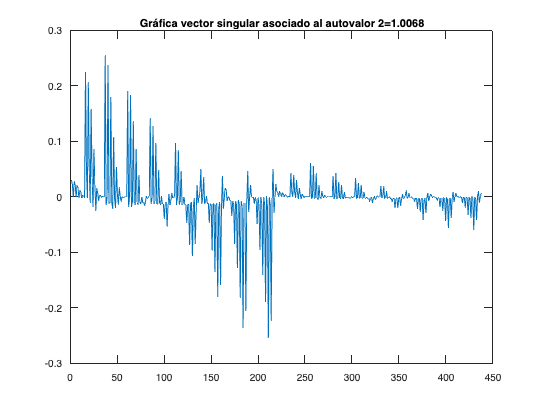

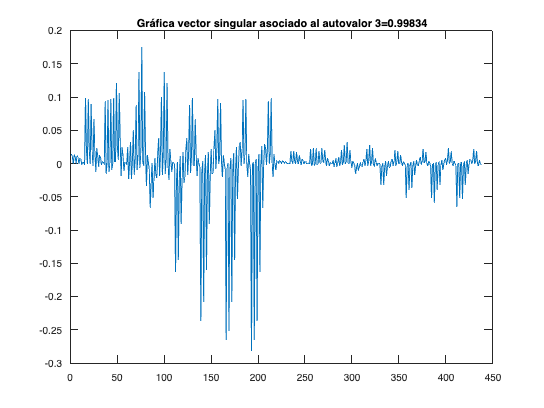

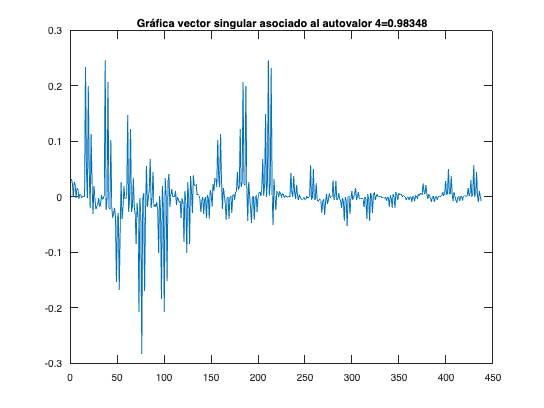

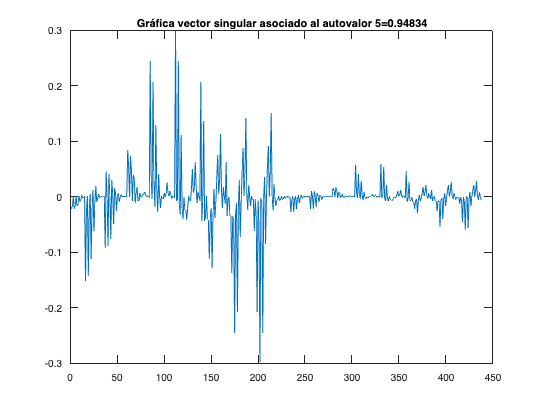

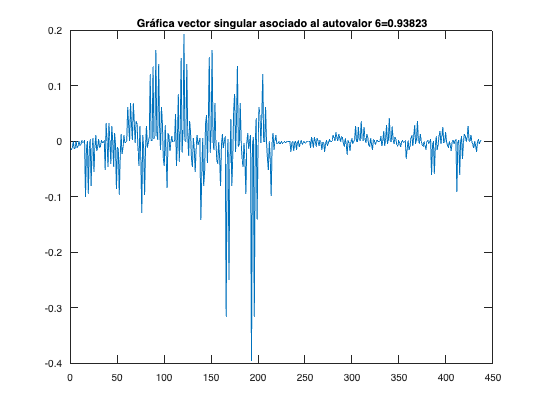

d=diag(D);
ind=find(d);
for i=1:6
    figure,
    plot(V(:,ind(i)))
    titulo = ['Gráfica vector singular asociado al autovalor ', num2str(i), '=',num2str(D(ind(i),ind(i))) ];
    title(titulo);
end

¿Que ocurre si se pretende resolver el mismo problema utilizando la expresión ( M^-1 * L) *x = lambda *x ?

Ahora vamos a resolverlo en formato denso, podeís examinar los recursos de memoria que se utilizan y el tiempo de computo. Analizar el proceso 

tic
[V1,D1]= eig(B,A);
disp('el tiempo de ejecución es:')

el tiempo de ejecución es:


toc

Elapsed time is 0.343235 seconds.


whos

  Name          Size               Bytes  Class     Attributes    

  A           438x438            1534752  double                  
  B           438x438            1534752  double                  
  D             6x6                  288  double                  
  D1          438x438            1534752  double                  
  L           438x438              62536  double    sparse        
  L11         219x219              29456  double    global, sparse
  L21         219x1                 1752  double    global        
  L22         219x219              29584  double    global, sparse
  M           438x438               8888  double    sparse        
  M11         219x1                 1752  double    global        
  M12         219x1                 1752  double    global        
  V           438x6                21024  double                  
  V1          438x438            1534752  double                  
  ans           1x1                    8  double             

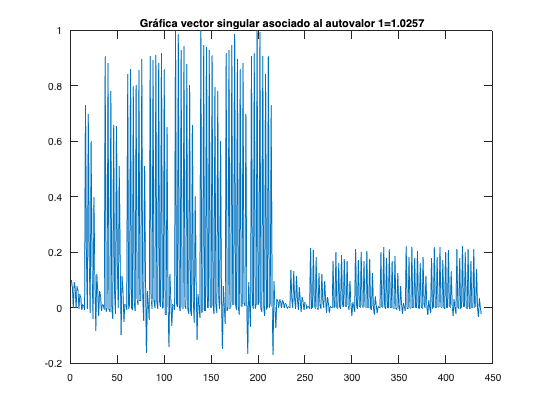

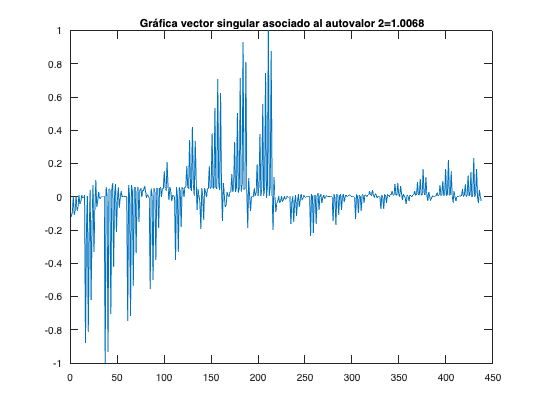

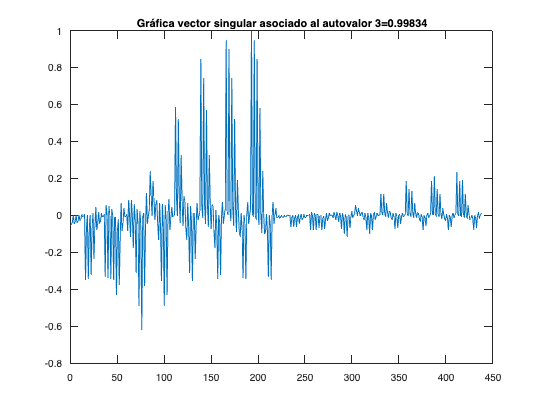

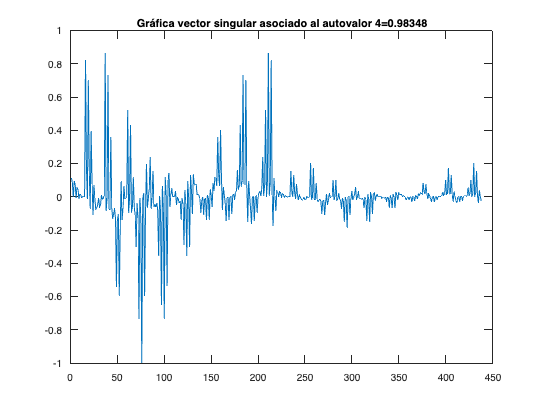

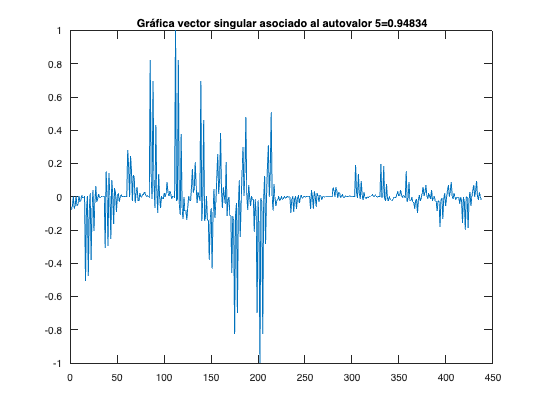

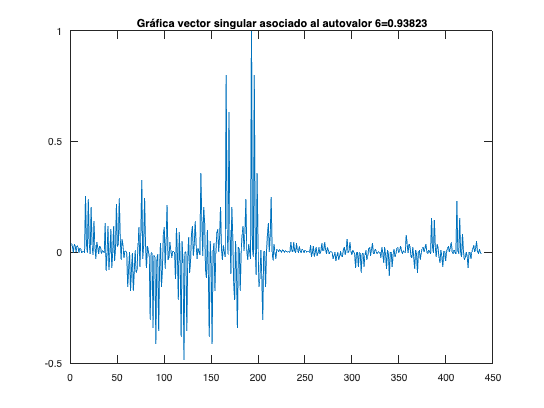

d=diag(D1); % se utiliza ya que los primeros 15 autovalores son nulos¡¡
x=find(d);
for i=1:6
    figure
    plot(V1(:,x(i)))
    titulo = ['Gráfica vector singular asociado al autovalor ', num2str(i), '=',num2str(d(x(i))) ];
    title(titulo);
end

Realiza el ejercicio 2 de la tarea 1.